### Analytic Fourier Series Coefficients

Because the guitar signal is a sampled recording, the Fourier series coefficients must be estimated numerically. However, if you have an analytic function, you can compute the Fourier coefficients using standard integrals.

 **Example. **Compute the Fourier coefficients of 


$$y(t) = 3 \cos(24 \pi t ) - 6 \sin (10 \pi  t)$$


assuming that $L = 0.5$ s.

Because $L = 0.5$, the Fourier series will have the form


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( 2 n \pi  t \right) + b_n \sin \left( 2 n \pi  t \right)$$


Comparing $y(t)$ to the Fourier series, it is clear that $a_n = 0$ except for $n = 12$ and $b_n = 0$ except for $n = 5$. Applying the integral formula for $a_{12}$:


$$ \begin{array}{rl} a_{12} &= \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt
\\
&=  2 \int_{-0.5}^{0.5} 3 \cos (24 \pi t) \cos \left( 24 \pi t \right)  - 6 \sin \left( 10 \pi t \right) \cos \left( 24 \pi t \right)dt
\\
&=  6 \int_{-0.5}^{0.5} \cos^2(24 \pi t) dt - 12  \int_{-0.5}^{0.5} \sin \left( 10 \pi t \right) \cos \left( 24 \pi t \right)dt
\end{array}
$$


Notice that the second integrand is the product of an odd (sine) and even (cosine) function, so it is odd. This implies that on the domain [-0.5,0.5], the second integral is zero. You can use a trigonometric identity to evaluate the first integral, or refer to an integral table. The result is


$$a_{12} =  6 \int_{-0.5}^{0.5} \cos^2(24 \pi t) dt = 6 \cdot 0.5 = 3
$$


This should be what you would expect by examining the original function $y(t)$. Compute the integral for the second term to find that $b_5 = -6$.

Run this section to see the function in the time domain and the Fourier coefficients in the frequency domain plotted below.

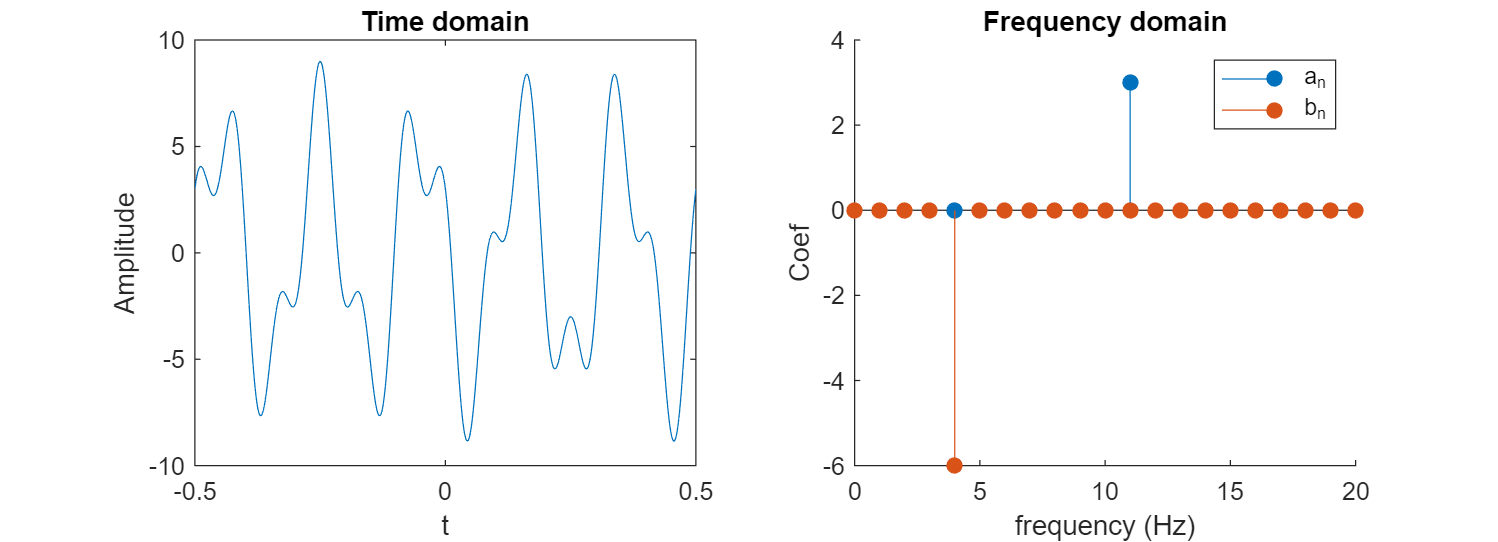

% The time domain signal
t = linspace(-0.5,0.5,500);
y = 3*cos(24*pi*t) - 6*sin(10*pi*t);

% Define the frequencies and the vectors for an and bn
freq = 0:20;
an = zeros(1,21);
bn = zeros(1,21);
an(12) = 3;
bn(5) = -6;

createFreqPlot(t, y, freq, an, bn); % Helper function that creates the plot

 **Exercise.** In this exercise, you will compute Fourier coefficients of a given function.

The 3 essential modes of the guitar A note audio recording can be represented by the function


$$y = 1.6 \sin( 2 \pi  \cdot110 t) + 4.8 \sin( 2 \pi \cdot 220 t) + 3.7 \sin( 2 \pi \cdot 330 t)$$


Note that the phase has been neglected and the function has been rescaled to make it easier to work with.

**Task 1.** By inspection, identify the Fourier series coefficients $a_n$ and $b_n$ in the definition


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


Assume that $L = 0.5$ s. 

**Task 2. **Use the integral formulas to analytically compute the first Fourier coefficient. Continue to assume that $L = 0.5$ s.  Does the results match what you calculated in **Task 1**?

**Task 3. **Complete the plot of the Fourier domain below by setting the values of `an` and `bn` to match your calculations in the previous tasks.

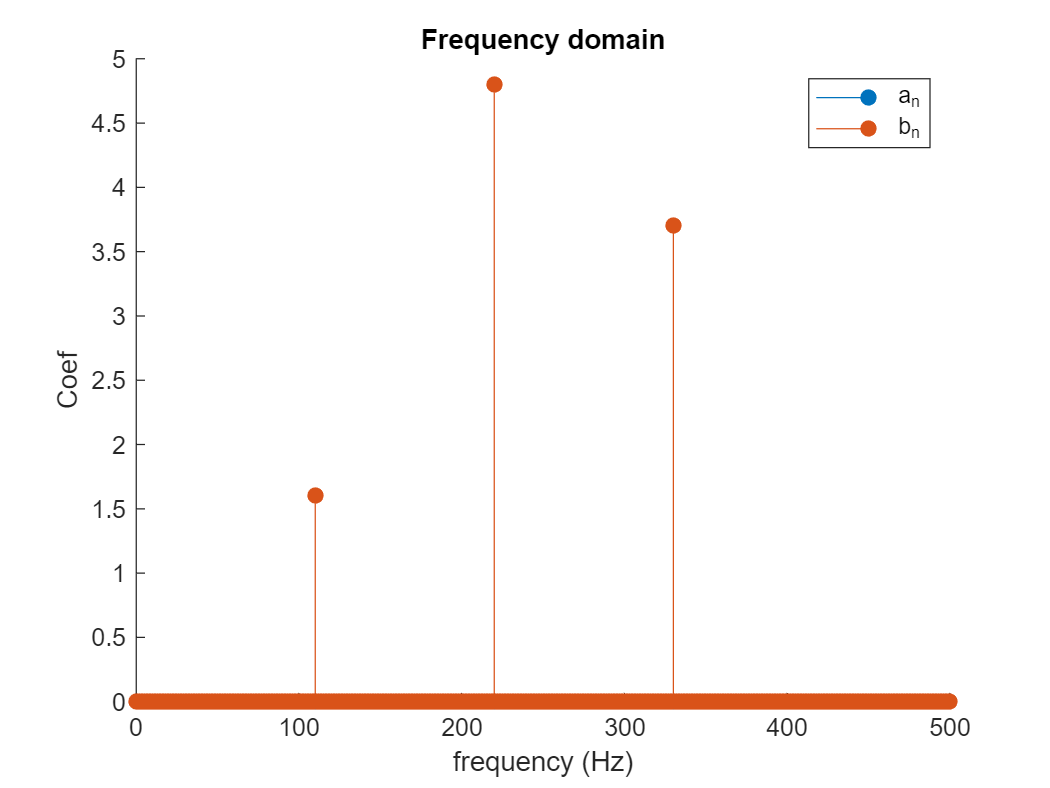

% Define the frequencies and the vectors for an and bn
freq = 0:500;
an = zeros(1,501);
bn = zeros(1,501);

% Adjust an and bn here to use the coefficients you calculated
% in Tasks 1 and 2.
bn(111) = 1.6;
bn(221) = 4.8;
bn(331) = 3.7;

% Create the plot
figure
hold on
stem(freq,an,"Filled")
stem(freq,bn,"Filled")
hold off
title("Frequency domain")
xlabel("frequency (Hz)")
ylabel("Coef")
legend("a_n","b_n")

You can also evaluate the Fourier series of other (periodic) functions. The process is the same: define the interval $L$ and then use the integral formulas to calculate the Fourier series coefficients.

 **Example. **Solve for the Fourier series of the odd square wave with period $2L$ and plot the result.

The odd square wave is pictured below. The coefficient integral is taken on the interval $[-L,L]$.

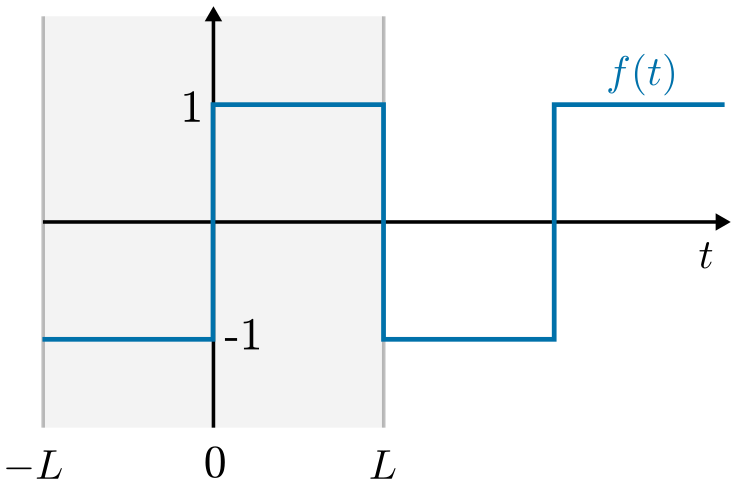

*Odd square wave*

The cosine coefficients $a_n$ are given by


$$a_n = \frac{1}{L} \int_{-L}^{L} f(t) \cos \left( \frac{ n \pi}{L} t \right) dt$$


Because $f(t)$ is odd and the cosine function is even, their product is odd. This implies that the integral is zero, so $a_n = 0$.

To solve for the sine coefficients $b_n$, split the integral on the intervals $[-L,0]$ and $[0,L]$.


$$\begin{array}{rl}
b_n &= \frac{1}{L} \int_{-L}^{L} f(t) \sin \left( \frac{n \pi }{L} t \right) dt 
\\
&=  \frac{1}{L} \left[ - \int_{-L}^{0}  \sin \left( \frac{n \pi}{L} t \right) dt + 
\int_{0}^{L} \sin \left( \frac{ n \pi}{L} t \right) dt  \right]
\end{array}$$


Evaluate the integral to find


$$\begin{array}{rl}
b_n &=  \frac{1}{n \pi} \left[ \left. \cos \left( \frac{n \pi}{L} t \right) \right|_{-L}^0 - 
\left. \cos \left( \frac{n \pi}{L} t \right) \right|_0^L  \right]
\\
&=  \frac{2}{n \pi} \left[ 1 - \cos(n \pi )]
\end{array}$$


Notice that for even $n$, $\cos( n \pi) = 1$, while if $n$ is odd $\cos(n \pi ) = -1$. This implies


$$b_n =
\left\{
\begin{array}{ll} 
0 & n \ \text{ even}
\\
\frac{4}{n \pi} & n \ \text{ odd}
\end{array}
\right.$$


Therefore, the Fourier series approximation of the square wave is


$$f_s(t) = \sum_{n=1,3,5,\ldots}^\infty \frac{4}{n \pi} \sin \left( \frac{ n \pi } {L}  t \right)$$


Use the slider below to view the partial series plotted alongside the original square wave function.

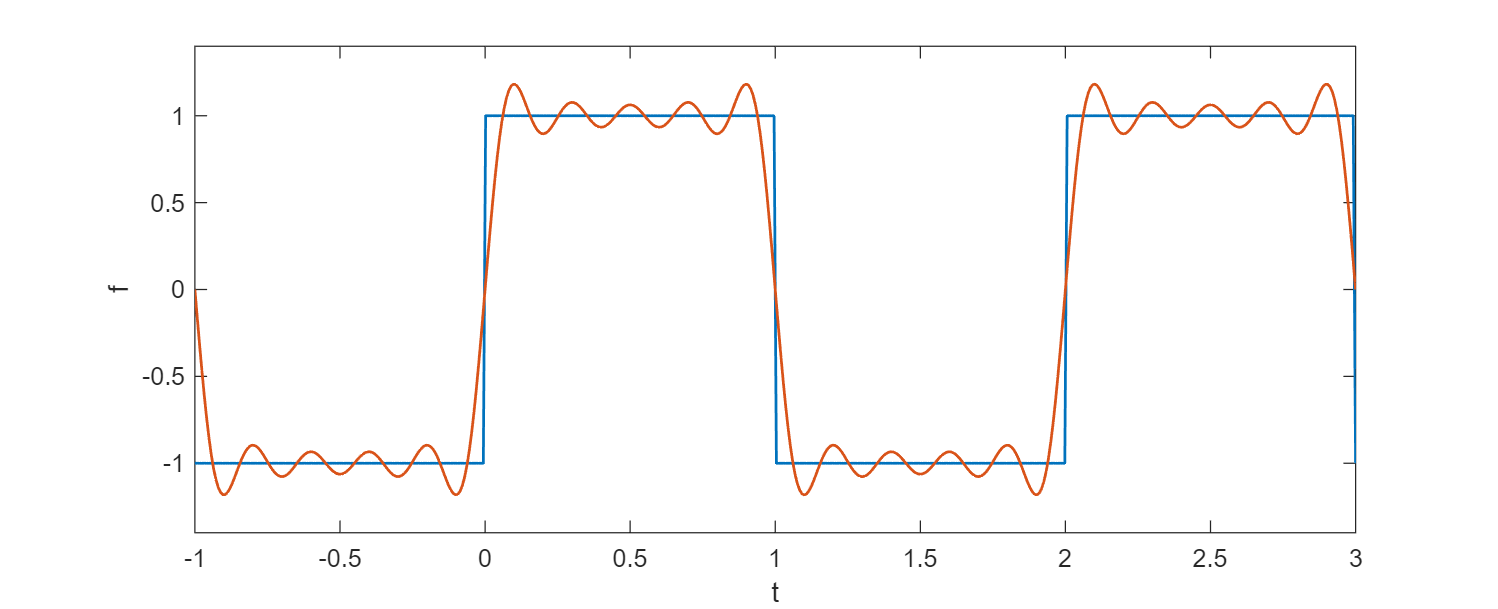

NModes = 5; % How many modes to use
plotSquareWaveSeries(NModes); % Helper function that generates the plot

function createFreqPlot(t, y, freq, an, bn)
    % Create the plot
    figure("position",[1,1,900,325])
    subplot(1,2,1)
    plot(t,y)
    title("Time domain")
    xlabel("t")
    ylabel("Amplitude")
    
    subplot(1,2,2)
    hold on
    stem(freq,an,"Filled")
    stem(freq,bn,"Filled")
    hold off
    title("Frequency domain")
    xlabel("frequency (Hz)")
    ylabel("Coef")
    legend("a_n","b_n")
end


function plotSquareWaveSeries(NModes)
    % Compute the coefficients
    L = 1;
    n = 1:2:(NModes*2);
    b = 4./(pi*n);
    
    % Sum the Fourier modes
    t = linspace(-L,3*L,500);
    fs = zeros(size(t));
    for k = 1:numel(n)
        fs = fs + b(k)*sin((n(k)*pi/L).*t);
    end
    f = square(t*pi/L);
    
    % Plot the result
    figure("position",[1,1,800,325])
    plot(t,f,t,fs,"linewidth",1.1)
    axis([-L,3*L,-1.4,1.4])
    xlabel("t")
    ylabel("f")
end
